# Getting Familiar

## Velocity

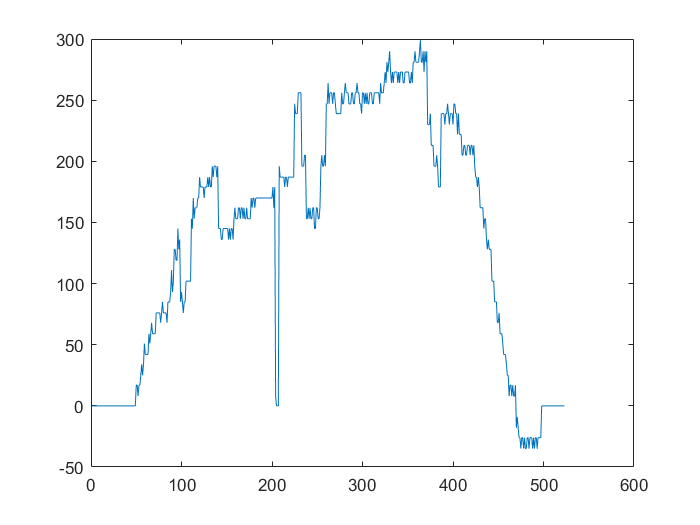

figure
plot(data_enc(:,9)) % Right velocity

## Wheels travelled distances

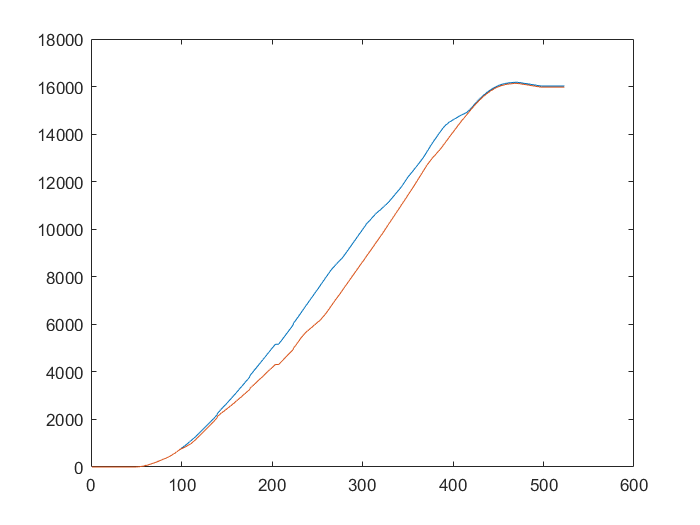

figure
plot(data_enc(:,6))
hold on
plot(data_enc(:,7))

## Wheels sample distance

figure
R=diff(data_enc(:,7)) % we lost one sample

R =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


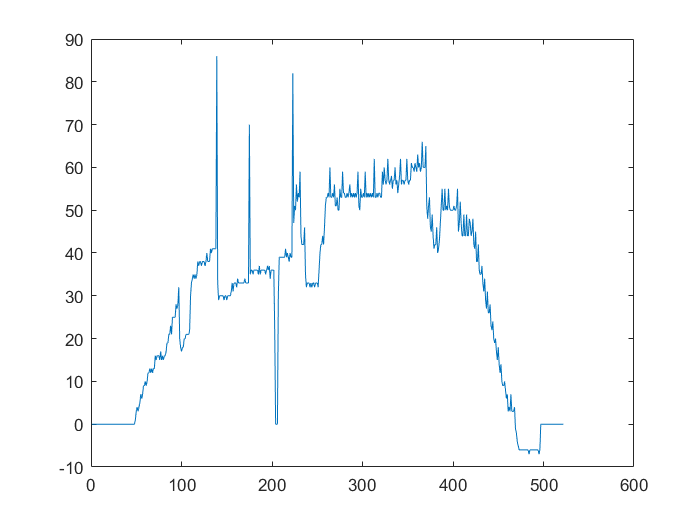

plot(R)

## Comparing Velocities

figure
Average_Ts=sum(diff(data_enc(:,1),1))/523

Average_Ts = 0.2144

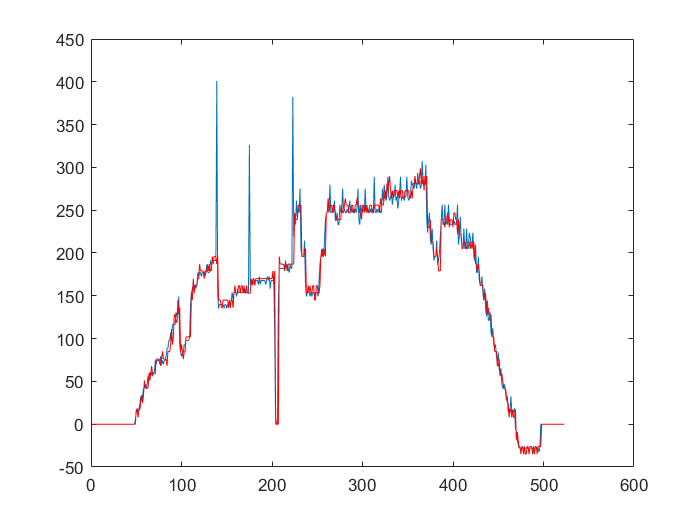

plot(R/Average_Ts)
hold on
plot(data_enc(:,9), 'r')

figure

## Laser Data

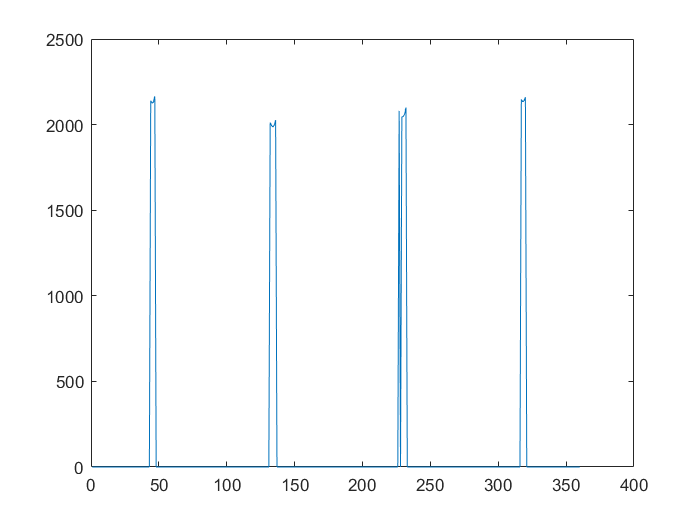

plot(lds_dis(8,2:end))

In Wordl RF is part of the exercise

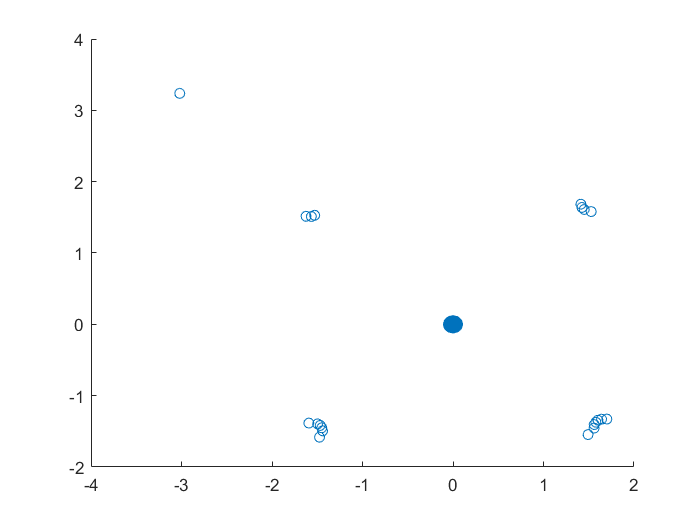

scatter( ldx(1,2:360),ldy(1,2:360))

## Visualizing all data

Taking a snapshot

x = inputdlg('Enter step time to visualize',... %Introducing the snapshot to visualize
             'Input', [1 20]);
index = str2num(x{:}) 

index = 1

Robot dimensions

Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle
for index=1:522 % Use the for loop to see a movie

Laser in robot frame

t = 0: 2*pi/359 : 2*pi;
P = polar(t, 4.5 * ones(size(t)));% to fix the limits
set(P, 'Visible', 'off')
subplot(1,2,1)
polar(t, lds_dis (index,2:361), '--g'); % Ploting the laser data wrt Robot frame
title ('Laser data at Robot Reference Frame','FontWeight','bold','FontSize',16)

subplot(1,2,2)
title ('Data on Wordl Reference Frame', 'FontWeight','bold','FontSize',16)
axis([-3 3 -2 4])
grid on
hold on
for i=1:4 % plotting the 4 Land Marks
circle (LandMark(i,:)',0.15)
end
scatter(ldx(index,:), ldy(index,:)) % plotting the land mark seen by the Robot wrt  wordl reference frame
plot (trajec(:,1), trajec(:,2), 'r.','LineWidth',1.5) % Plotting the trajectory
Robot_tr=transl(trajec(index,1),trajec(index,2),0)*trotz(mod(trajec(index,3)+pi/2,2*pi))*Robot;% moving the robot 
patch(Robot_tr(1,:), Robot_tr(2,:),'b');

plot_ellipse(pk.signals.values(1:2,1:2,index),[trajec(index,1), trajec(index,2)],'g'); % Plotting the covariance matrix
pause(0.01);
clf
end